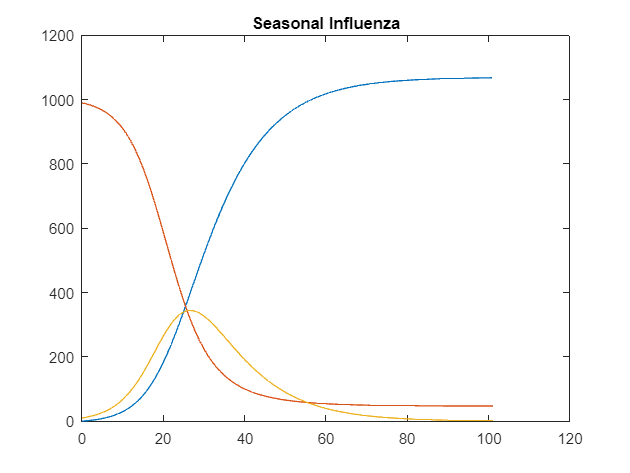


% Initial Values
I0 = 10;
S0 = 990;
R0 = 0;

N = I0 + S0 + R0;
Betai = .3; Gammai = .1;
Betaii = 1; Gammaii = .1;
Betaiii = 2; Gammaiii = .2;
h = 1;
t0 = 0; tf = 100;

Rnext = @(R,h,RK1,RK2,RK3,RK4) R + (1/6) * (RK1 + 2*(RK2) + 2*(RK3) + RK4) * h;
Snext = @(S,h,SK1,SK2,SK3,SK4) S + (1/6) * (SK1 + 2*(SK2) + 2*(SK3) + SK4) * h;
Inext = @(I,h,IK1,IK2,IK3,IK4) I + (1/6) * (IK1 + 2*(IK2) + 2*(IK3) + IK4) * h;

dRdt = @(Gamma,I) Gamma*I;                  
dSdt = @(I,Beta,N,S) -(Beta/N)*S*I;
dIdt = @(Gamma,I,Beta,N,S) (Beta/N)*S*I-Gamma*I;

RK1 = @(Gamma,I,h) dRdt(Gamma,I);           % Runge Kutta Recovered K1 
RK2 = @(Gamma,I,h) dRdt(Gamma,(I+.5*(RK1(Gamma,I,h))*h));           % Runge Kutta Recovered K2 
RK3 = @(Gamma,I,h) dRdt(Gamma,(I+.5*(RK2(Gamma,I,h))*h));           % Runge Kutta Recovered K3 
RK4 = @(Gamma,I,h) dRdt(Gamma,(I+(RK3(Gamma,I,h))*h));           % Runge Kutta Recovered K4 

SK1 = @(I,Beta,N,S,h) dSdt(I,Beta,N,S);           % Runge Kutta Susceptible K1 
SK2 = @(I,Beta,N,S,h) dSdt(I,Beta,N,S+.5*SK1(I,Beta,N,S)*h);           % Runge Kutta Susceptible K2
SK3 = @(I,Beta,N,S,h) dSdt(I,Beta,N,S+.5*SK2(I,Beta,N,S,h)*h);           % Runge Kutta Susceptible K3 
SK4 = @(I,Beta,N,S,h) dSdt(I,Beta,N,S+SK3(I,Beta,N,S,h)*h);           % Runge Kutta Susceptible K4 

IK1 = @(Gamma,I,Beta,N,S,h) dIdt(Gamma,I,Beta,N,S);
IK2 = @(Gamma,I,Beta,N,S,h) dIdt(Gamma,I+.5*IK1(Gamma,I,Beta,N,S)*h,Beta,N,S);
IK3 = @(Gamma,I,Beta,N,S,h) dIdt(Gamma,I+.5*IK2(Gamma,I,Beta,N,S,h)*h,Beta,N,S);
IK4 = @(Gamma,I,Beta,N,S,h) dIdt(Gamma,I+IK3(Gamma,I,Beta,N,S,h)*h,Beta,N,S);

% Seasonal Inluenza
I=I0;
S = S0;
R=R0;
Gamma=Gammai;
Beta=Betai;


time = t0:h:tf+1;
Rvals = zeros(size(time)-1);
Svals = zeros(size(time)-1);
Ivals = zeros(size(time)-1);

Rvals(1) = R0;
Svals(1) = S0;
Ivals(1) = I0;

% Seasonal Inluenza
for i = 1:101
R=Rvals(i);
S=Svals(i);
I=Ivals(i);

Rvals(i+1) = Rnext(R,h,RK1(Gamma,I,h),RK2(Gamma,I,h),RK3(Gamma,I,h),RK4(Gamma,I,h));
Svals(i+1) = Snext(S,h,SK1(I,Beta,N,S,h),SK2(I,Beta,N,S,h),SK3(I,Beta,N,S,h),SK4(I,Beta,N,S,h));
Ivals(i+1) = Inext(I,h,IK1(Gamma,I,Beta,N,S,h),IK2(Gamma,I,Beta,N,S,h),IK3(Gamma,I,Beta,N,S,h),IK4(Gamma,I,Beta,N,S,h));

end

plot(time,Rvals);
hold on;
plot(time,Svals);
plot(time,Ivals);
title('Seasonal Influenza');
hold off;

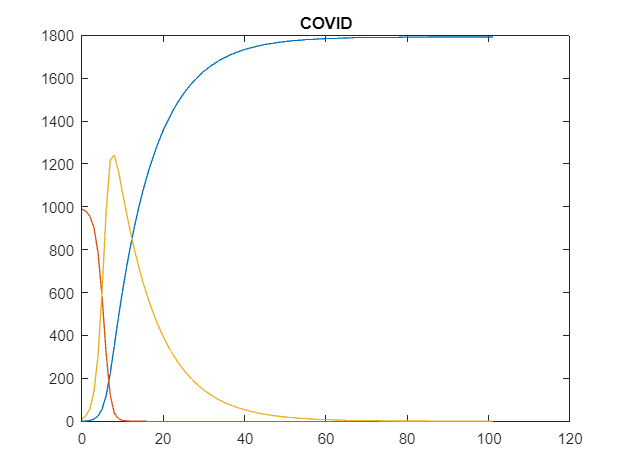


% COVID
I=I0;
S = S0;
R=R0;
Gamma=Gammaii;
Beta=Betaii;


R2vals = zeros(size(time)-1);
S2vals = zeros(size(time)-1);
I2vals = zeros(size(time)-1);

R2vals(1) = R0;
S2vals(1) = S0;
I2vals(1) = I0;

% COVID
for i = 1:101
R=R2vals(i);
S=S2vals(i);
I=I2vals(i);

R2vals(i+1) = Rnext(R,h,RK1(Gamma,I,h),RK2(Gamma,I,h),RK3(Gamma,I,h),RK4(Gamma,I,h));
S2vals(i+1) = Snext(S,h,SK1(I,Beta,N,S,h),SK2(I,Beta,N,S,h),SK3(I,Beta,N,S,h),SK4(I,Beta,N,S,h));
I2vals(i+1) = Inext(I,h,IK1(Gamma,I,Beta,N,S,h),IK2(Gamma,I,Beta,N,S,h),IK3(Gamma,I,Beta,N,S,h),IK4(Gamma,I,Beta,N,S,h));

end

plot(time,R2vals);
hold on;
plot(time,S2vals);
plot(time,I2vals);
title('COVID');
hold off;

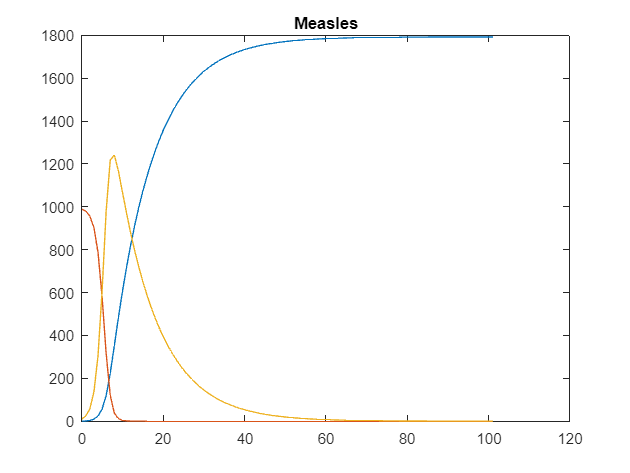


% Measles
I=I0;
S = S0;
R=R0;
Gamma=Gammaii;
Beta=Betaii;


R3vals = zeros(size(time)-1);
S3vals = zeros(size(time)-1);
I3vals = zeros(size(time)-1);

R3vals(1) = R0;
S3vals(1) = S0;
I3vals(1) = I0;

% Measles
for i = 1:101
R=R3vals(i);
S=S3vals(i);
I=I3vals(i);

R3vals(i+1) = Rnext(R,h,RK1(Gamma,I,h),RK2(Gamma,I,h),RK3(Gamma,I,h),RK4(Gamma,I,h));
S3vals(i+1) = Snext(S,h,SK1(I,Beta,N,S,h),SK2(I,Beta,N,S,h),SK3(I,Beta,N,S,h),SK4(I,Beta,N,S,h));
I3vals(i+1) = Inext(I,h,IK1(Gamma,I,Beta,N,S,h),IK2(Gamma,I,Beta,N,S,h),IK3(Gamma,I,Beta,N,S,h),IK4(Gamma,I,Beta,N,S,h));

end

plot(time,R3vals);
hold on;
plot(time,S3vals);
plot(time,I3vals);
title('Measles');
hold off;